## Tutorial 6 - Problem 4a-c

clc; clear all; close all;

J_m = 0.004; % kg*m^2
J_eff = J_m;

U_a_max = 12; % V
R_a = 1.1; % Ohm
K_m = 0.2; % Nm/A
% L is neglected
M_L = 0; % Load on motor is neglected

K_sys = 0.9; % Steady state speed

zeta = 0.6; % Damping

% a)
K_p = 1/4 * K_m^3/(R_a*J_eff*zeta^2) % Equation 7.16 from notes

K_p =           1.26262626262626



% b)
omega_sys = sqrt((K_m*K_p)/(R_a*J_eff)) % Equation 7.14 from notes

omega_sys =           7.57575757575758


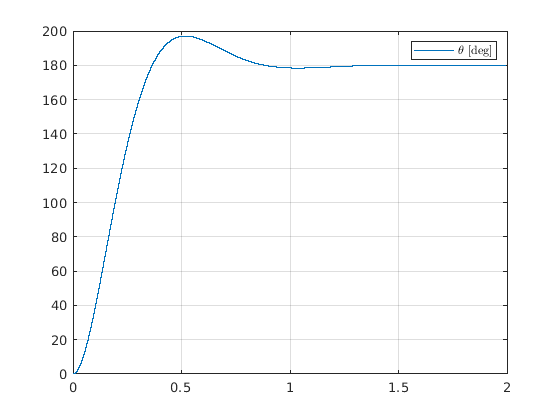


% c)
theta_ref = deg2rad(180); % s
theta = 0; % rad
thetaDot = 0; % rad/s
simTime = 2; % s

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    
    % Calculations
    U_a = K_p * (theta_ref - theta);

    if(U_a >= U_a_max)
        U_a = U_a_max;
    end

    i_a = (U_a - K_m*thetaDot)/R_a;
    M_m = K_m * i_a;
    thetaDotDot = (M_m-M_L)/J_eff;

    % Logging
    time_plot(idx) = t;
    theta_plot(idx) = theta;
    % Time integrate
    theta = theta + thetaDot * dt;
    thetaDot = thetaDot + thetaDotDot * dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(time_plot, rad2deg(theta_plot))
legend("$\theta$ [deg]", 'Interpreter','latex')
grid

## Tutorial 6 - Problem 4d

clc; clear all;

J_m = 0.004; % kg*m^2
J_eff = J_m;

U_a_max = 12; % V
R_a = 1.1; % Ohm
K_m = 0.2; % Nm/A
% L is neglected
M_L = 0; % Load on motor is neglected

K_sys = 0.9; % Steady state speed

zeta = 0.6; % Damping

% a)
K_p = 1/4 * K_m^3/(R_a*J_eff*zeta^2) % Equation 7.16 from notes

K_p =           1.26262626262626



% b)
omega_sys = sqrt((K_m*K_p)/(R_a*J_eff)) % Equation 7.14 from notes

omega_sys =           7.57575757575758


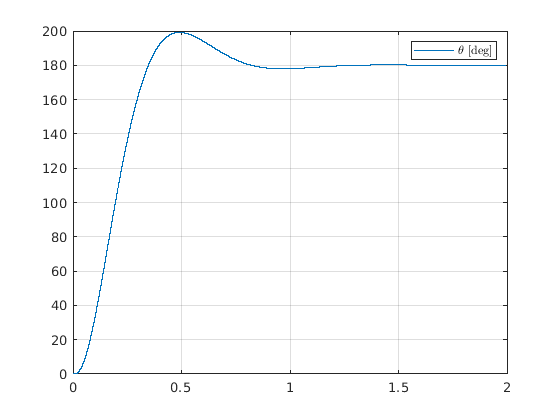


% d)
theta_ref = deg2rad(180); % s
theta = 0; % rad
thetaDot = 0; % rad/s
simTime = 2; % s
L_a = 0.015; % H
i_a = 0;

t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    
    % Calculations
    U_a = K_p * (theta_ref - theta);

    if(U_a >= U_a_max)
        U_a = U_a_max;
    end

    %i_a = (U_a - K_m*thetaDot)/R_a;
    i_a_dot = 1/L_a * (U_a - R_a*i_a - K_m*thetaDot);
    M_m = K_m * i_a;
    thetaDotDot = (M_m-M_L)/J_eff;

    % Logging
    time_plot(idx) = t;
    theta_plot(idx) = theta;
    % Time integrate
    i_a = i_a + i_a_dot * dt;
    theta = theta + thetaDot * dt;
    thetaDot = thetaDot + thetaDotDot * dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(time_plot, rad2deg(theta_plot))
legend("$\theta$ [deg]", 'Interpreter','latex')
grid